# 数值计算 上机作业 Chapter5

### 李宇豪    21305412

对于区间 [-1, 1] 上的函数 


$$f(x) = \frac{1}{1+ 25  x^2}$$


## 等距节点 Lagrange 多项式插值

设置插值多项式次数

n_range = 2:4:16

n_range =      2     6    10    14


作图观察

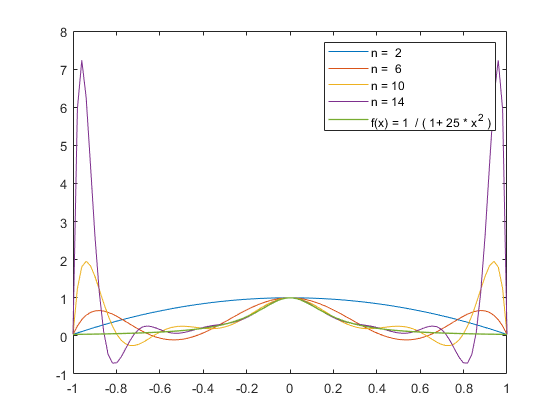

figure
for n = n_range
    [x, f] = runge_eq(n); % 等距节点
    [xx, Ly] = lagrange_int(x, f);
    plot(xx, Ly)
    hold on
end

ff = 1 ./ ( 1 + 25 * xx.^2 );
plot(xx, ff, "LineWidth", 1)

tag = strcat("n = ",num2str((n_range)'));
legend([tag','f(x) = 1  / ( 1+ 25 * x^2 )'])

可以看到，插值次数较高时，在零附近（-0.2~0.2）插值函数和原函数的偏差较小，插值效果较好

但是在 1 和 -1 的附近，插值误差随着插值次数的增高而显著增大。

## 非等距节点 Lagrange 多项式插值

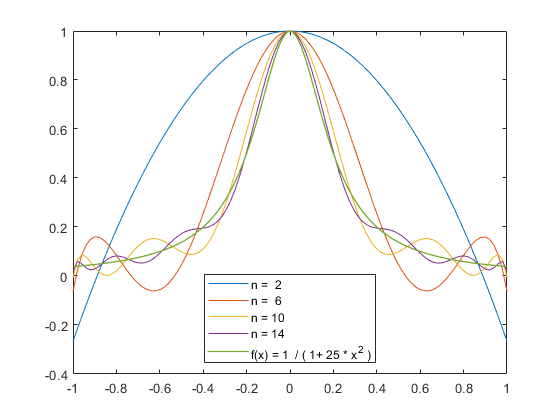

figure
for n = n_range
    [x, f] = runge_neq(n); % 构造 Chebyshev 节点
    [xx, Ly] = lagrange_int(x, f);
        % Lagrange 插值
    plot(xx, Ly)
    hold on
end

ff = 1 ./ ( 1 + 25 * xx.^2 );
plot(xx, ff, 'LineWidth', 1)

tag = strcat("n = ",num2str((n_range)'));
legend([tag','f(x) = 1  / ( 1+ 25 * x^2 )'], 'Location','South')

可以看到，高次的插值在区间边缘仍有振荡，但是相比于等距节点的插值，此时误差已经小了很多，

说明Chebyshev 节点避免了插值误差在区间边缘的发散。

## 附：用到的函数定义

function [x, f] = runge_eq(n)
% 构造等距节点
    x = linspace(-1, 1, n+1);
    f = 1  ./ ( 1 + 25 * x.^2 );
end

function [xx, Ly] = lagrange_int(x, f)
% Lagrange 插值
    m = length(x);
    xx = (linspace(-1, 1, 100))';
    
    L = ones([length(xx), m]);
    for i = 1:m
        L(:,i) = l_cell(xx, x, i);
    end
    
    Ly = L * f';
    Ly = Ly';
end

function li = l_cell(xx, x, i)
% 计算lagrange多项式的每个基
    frac_s = ( xx - x )';  
    frac_m = ( x(i) - x )';
    frac_s(i,:) = [];
    frac_m(i,:) = [];
    
    li = ( prod(frac_s) / prod(frac_m) )';
end

function [x, f] = runge_neq(n)
% 构造Chebyshev节点
    m = n + 1;
    k = 0:n;
    
    x = cos( (2*k+1)*pi / (2*m) );
    f = 1  ./ ( 1 + 25 * x.^2 );
end